clear ,clc, close all

CARICAMENTO ROBOT e INIZIALIZZAZIONI

[ned2, numJoints] = ned2_import;
ned2.DataFormat = "row";
initialguess = ned2.homeConfiguration ;
chomp = manipulatorCHOMP(ned2);
chomp.CollisionOptions.IgnoreSelfCollision = true ;
ik = inverseKinematics("RigidBodyTree", ned2);
weight = [0.1 0.1 0 1 1 1];
%figure
%show(ned2,ned2.homeConfiguration,"Visuals","off","Collisions","on");

%ned2.Bodies


## Generazione Ambiente

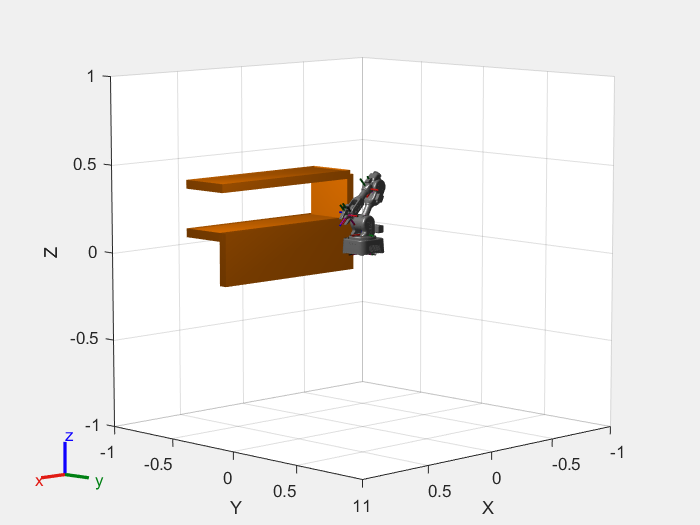

a = 0.15; % distanza mura- manipolatore
b = 0.1 ;  %parametro per far scendere muro superiore
wallLength = 1;   % Lunghezza in X [m]
wallHeight = 0.3;   % Altezza in Z [m]
wallThickness = 0.05; % Spessore in Y [m]
wallCenter = [0.25, -0.2-a, 0]; % Posizione centro muro [x y z]
wall = collisionBox(wallLength, wallThickness, wallHeight);  
wall.Pose = trvec2tform(wallCenter);  % posizioneMuro(x, y, z)
% wall superiore
% wall 1
wallLength1 =1;   % Lunghezza in X [m]
wallHeight1 = 0.05;   % Altezza in Z [m]
wallThickness1 = 0.3; % Spessore in Y [m]

wallCenter1 = [0.25, -0.35-a, (0.5-b)]; % Posizione centro muro [x y z]
wall1 = collisionBox(wallLength1, wallThickness1, wallHeight1);  
wall1.Pose = trvec2tform(wallCenter1);  % posizioneMuro(x, y, z)

%wall 4 --> PAVIMENTO 

wallLength4 = 1;   % Lunghezza in X [m]  scaffale
wallHeight4 = 0.05;   % Altezza in Z [m]
wallThickness4 = 0.3; % Spessore in Y [m]
wallCenter4 = [0.25, -0.35-a, 0.125]; % Posizione centro muro [x y z]
wall4 = collisionBox(wallLength4, wallThickness4, wallHeight4);  
wall4.Pose = trvec2tform(wallCenter4);  % posizioneMuro(x, y, z)

% wall 5 --> parete dx

wallLength5 = 0.05;   % Lunghezza in X [m]
wallHeight5 = 0.4;   % Altezza in Z [m]
wallThickness5 = 0.3; % Spessore in Y [m]
wallCenter5 = [-0.25, -0.35-a, (0.3-b)]; % Posizione centro muro [x y z]
wall5 = collisionBox(wallLength5, wallThickness5, wallHeight5);  
wall5.Pose = trvec2tform(wallCenter5);  % posizioneMuro(x, y, z)

show(ned2);
hold on
show(wall)
hold on
show(wall1)
hold on
show(wall4)
hold on
show(wall5)
hold on

Workspace analysis

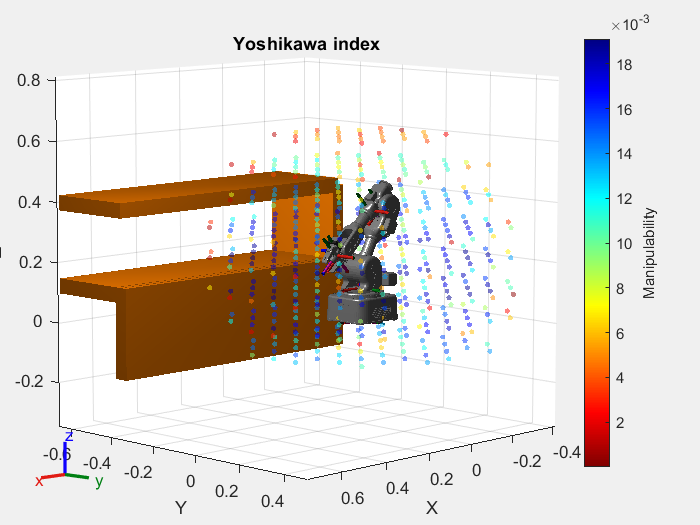

ned2.Gravity = [0 0 -9.81];
ee = "gripper_link" ;
[wksp,cfgs] = generateRobotWorkspace(ned2,{wall,wall1,wall4,wall5},IgnoreSelfCollision="on");
mIndexYoshikawa = manipulabilityIndex(ned2,cfgs,IndexType="yoshikawa");
%% 
figure
show(ned2);
hold on
show(wall);
hold on
show(wall1);
hold on
show(wall4);
hold on
show(wall5);
hold on

showWorkspaceAnalysis(wksp,mIndexYoshikawa);
hold off
title("Yoshikawa index");
axis auto

PUNTI RAGGIUNGIBILI (solo da ver 2024b, io ho 2024a)

% PUNTO ESEMPIO (trovato post analisi yoshikawa)

puntoTarget = [0.198064711486166,0.272414567734862,-0.081808696119091];
targetPose = trvec2tform(puntoTarget)*axang2tform([0 1 0 pi]);

[pick, solInfo] = ik("gripper_link", targetPose, weight, initialguess);

place =  [0.096306675730951,-0.419791864993828,0.221967843573256];
targetPlace = trvec2tform(place);

targetPlace = trvec2tform(place)*axang2tform([0 1 0 pi]);
[placeConfig, solInfo1] = ik("gripper_link", targetPlace, weight, pick);

GENERAZIONE SFERE DI WALL  e CILINDRO

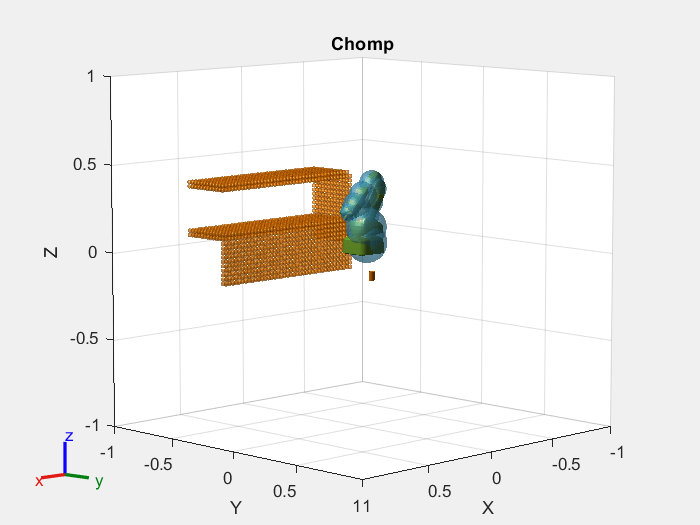

spheresPerMeter = 20; % sfere per metro (risoluzione)%% Calcolo numero di sfere lungo ogni asse
nx = ceil(wallLength * spheresPerMeter);
ny = ceil(wallThickness * spheresPerMeter);
nz = ceil(wallHeight * spheresPerMeter);
sphereRadius = min([wallLength/nx, wallThickness/ny, wallHeight/nz]) / 2;  % Raggio delle sfere
sphereRadiusCyl = 0.015 ; 
cyl = collisionCylinder(sphereRadiusCyl, 0.05);
sphObstacles = exampleHelperApproximateCollisionBoxSpheres(wall,sphereRadius);
sphObstacles1 = exampleHelperApproximateCollisionBoxSpheres(wall1,sphereRadius);
sphObstacles4 = exampleHelperApproximateCollisionBoxSpheres(wall4,sphereRadius);
sphObstacles5 = exampleHelperApproximateCollisionBoxSpheres(wall5,sphereRadius);
cyl.Pose = targetPose ;
sph = exampleHelperApproximateCollisionCylinderSpheres(cyl,sphereRadiusCyl);
sphObstacles_total = [sphObstacles sphObstacles1  sphObstacles4 sphObstacles5];
sphbstacles = [sphObstacles_total sph];
chomp.SphericalObstacles = sphbstacles;

% Visualizzazione
figure;
show(chomp);
title('Chomp');
hold on
show(cyl);

Traiettoria ottimizzata che evita muro

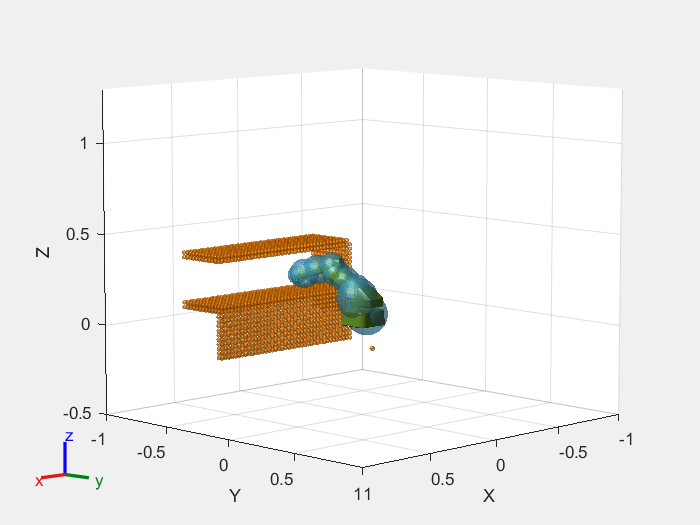

startconfig = homeConfiguration(ned2);
timepoints = [0 5];
timestep = 0.1;
placeConfig(1,6) = -placeConfig(1,6)/2 ;

trajtype = "minjerkpolytraj"; %"minjerkpolytraj";"quinticpolytraj";"interp1" sono tutte le tipologie di traiettorie 

chomp.CollisionOptions.CollisionCostWeight = 1;
chomp.SmoothnessOptions.SmoothnessCostWeight = 1e-3;
chomp.SolverOptions.LearningRate = 5;

[wptsamples, tsamples] = optimize(chomp,[startconfig; pick;],timepoints,timestep,InitialTrajectoryFitType=trajtype); %pick

[wpt1, ts1] = optimize(chomp,[pick; placeConfig],timepoints,timestep,InitialTrajectoryFitType=trajtype); %place

figure;
show(chomp,wpt1(51,:),NumSamples=10);
zlim([-0.5 1.3]);

ANIMAZIONE

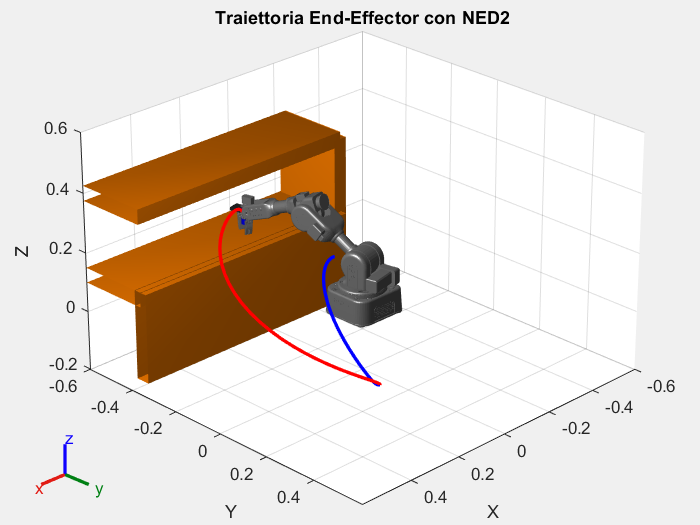

% Calcolo la traiettoria dell'end-effector da wptsamples ----> PICK
eeTrajectory = zeros(size(wptsamples,1), 3);

for i = 1:size(wptsamples,1)
    config = wptsamples(i,:);
    % Estrai trasformazione dell’end-effector (ultimo link del NED2)
    tform = getTransform(ned2, config, 'gripper_link');
    eeTrajectory(i,:) = tform(1:3,4)';
end
% Calcolo la traiettoria dell'end-effector da wpt1 ----> PLACE
eeTrajectory1 = zeros(size(wpt1,1), 3);

for i = 1:size(wpt1,1)
    config1 = wpt1(i,:);
    % Estrai trasformazione dell’end-effector (ultimo link del NED2)
    tform1 = getTransform(ned2, config1, ned2.BodyNames{end});
    eeTrajectory1(i,:) = tform1(1:3,4)';
end


% Inizializza la figura
figure;
ax = axes;
show(ned2, wptsamples(1,:), 'Parent', ax, 'PreservePlot', false, 'Frames', 'off');
hold on
show(ned2, wpt1(1,:), 'Parent', ax, 'PreservePlot', false, 'Frames', 'off');
hold on;
grid on;
view(135, 25);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Traiettoria End-Effector con NED2');
% axis equal;

xlim([-0.6 0.6]);
ylim([-0.6 0.6]);
zlim([0 1.2]);

% cose per cilindro animazione
[~,p] = show(cyl);
p.FaceAlpha = 0.25;
[~,patchOfObjectToBePicked]=show(cyl);
patchOfObjectToBePicked.FaceColor=[0,0,1];
hgtform=hgtransform();
patchOfObjectToBePicked.Parent=hgtform;
pickConfig=wpt1(1,:);
Tcanwrtee=getTransform(ned2,pickConfig,'gripper_link')\cyl.Pose;

% Plotta la traiettoria dell’end-effector


show(ned2); hold on
show(wall); hold on
show(wall1); hold on
show(wall4); hold on
show(wall5); hold on
% show(cyl); hold on
 zlim([-0.2 0.6])
% Anima il manipolatore lungo la traiettoria
 plot3(eeTrajectory(:,1), eeTrajectory(:,2), eeTrajectory(:,3), 'b-', 'LineWidth', 2);
hold on
for i = 1:size(wptsamples,1)
    show(ned2, wptsamples(i,:), 'Parent', ax, 'PreservePlot', false, 'Frames', 'off');
    plot3(eeTrajectory(1:i,1), eeTrajectory(1:i,2), eeTrajectory(1:i,3), 'b-', 'LineWidth', 2);
    pause(0.05); % per animazione fluida

end
delete(p);
plot3(eeTrajectory1(:,1), eeTrajectory1(:,2), eeTrajectory1(:,3), 'r-', 'LineWidth', 2);
hold on
for i = 1:size(wpt1,1)
    show(ned2, wpt1(i,:), 'Parent', ax, 'PreservePlot', false, 'Frames', 'off');
    plot3(eeTrajectory1(1:i,1), eeTrajectory1(1:i,2), eeTrajectory1(1:i,3), 'r-', 'LineWidth', 2);
    config=wpt1(i,:);
     eePose=getTransform(ned2,config,'gripper_link');
    hgtform.Matrix=((eePose*Tcanwrtee)/cyl.Pose);
    pause(0.05); % per animazione fluida

end